disp("Independent Work 05.")

Independent Work 05.


disp("Question 01.")

Question 01.


% Defining of system
f = @(t, z) [z(2); -z(1)^3 + 9*z(1)];  

% Defining of grid
[x, y] = meshgrid(-5:0.2:5, -5:0.2:5);  

% Defining of derivatives
dx = y;  
dx(1,:)

ans =     -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


dy = -x.^3 + 9*x; 
dy(1,:)

ans =    80.0000   67.3920   55.9360   45.5840   36.2880   28.0000   20.6720   14.2560    8.7040    3.9680         0   -3.2480   -5.8240   -7.7760   -9.1520  -10.0000  -10.3680  -10.3040   -9.8560   -9.0720   -8.0000   -6.6880   -5.1840   -3.5360   -1.7920         0    1.7920    3.5360    5.1840    6.6880    8.0000    9.0720    9.8560   10.3040   10.3680   10.0000    9.1520    7.7760    5.8240    3.2480         0   -3.9680   -8.7040  -14.2560  -20.6720  -28.0000  -36.2880  -45.5840  -55.9360  -67.3920



% Normalizing of vectors
L = sqrt(dx.^2 + dy.^2);
L(1,:)

ans =    80.1561   67.5772   56.1590   45.8574   36.6308   28.4429   21.2681   15.1074   10.0379    6.3832    5.0000    5.9623    7.6759    9.2448   10.4288   11.1803   11.5107   11.4531   11.0517   10.3586    9.4340    8.3504    7.2024    6.1240    5.3114    5.0000    5.3114    6.1240    7.2024    8.3504    9.4340   10.3586   11.0517   11.4531   11.5107   11.1803   10.4288    9.2448    7.6759    5.9623    5.0000    6.3832   10.0379   15.1074   21.2681   28.4429   36.6308   45.8574   56.1590   67.5772


dx = dx ./ L;  
dx(1,:)

ans =    -0.0624   -0.0740   -0.0890   -0.1090   -0.1365   -0.1758   -0.2351   -0.3310   -0.4981   -0.7833   -1.0000   -0.8386   -0.6514   -0.5408   -0.4794   -0.4472   -0.4344   -0.4366   -0.4524   -0.4827   -0.5300   -0.5988   -0.6942   -0.8165   -0.9414   -1.0000   -0.9414   -0.8165   -0.6942   -0.5988   -0.5300   -0.4827   -0.4524   -0.4366   -0.4344   -0.4472   -0.4794   -0.5408   -0.6514   -0.8386   -1.0000   -0.7833   -0.4981   -0.3310   -0.2351   -0.1758   -0.1365   -0.1090   -0.0890   -0.0740


dy = dy ./ L;
dy(1,:)

ans =     0.9981    0.9973    0.9960    0.9940    0.9906    0.9844    0.9720    0.9436    0.8671    0.6216         0   -0.5448   -0.7587   -0.8411   -0.8776   -0.8944   -0.9007   -0.8997   -0.8918   -0.8758   -0.8480   -0.8009   -0.7198   -0.5774   -0.3374         0    0.3374    0.5774    0.7198    0.8009    0.8480    0.8758    0.8918    0.8997    0.9007    0.8944    0.8776    0.8411    0.7587    0.5448         0   -0.6216   -0.8671   -0.9436   -0.9720   -0.9844   -0.9906   -0.9940   -0.9960   -0.9973


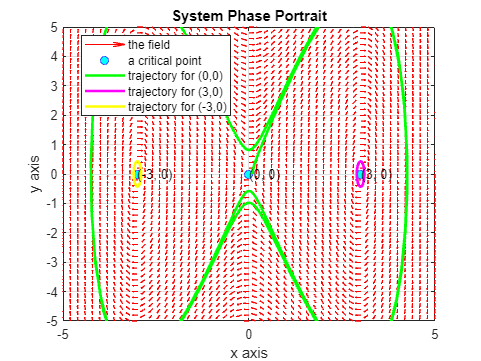


% Plotting of visualization
figure;
quiver(x, y, dx, dy, 'r', 'AutoScaleFactor', 0.5);
hold on;

% Setting of limits
axis([-5 5 -5 5]);  
xlabel('x axis');
ylabel('y axis');
title('System Phase Portrait');

% Adding of critical points
cri_poi = [0, 0; 3, 0; -3, 0];  
plot(cri_poi(:,1), cri_poi(:,2), 'bo', 'MarkerFaceColor', 'cyan');

% Solving of trajectories
tspan = [0 10];

% Plotting of a trajectory for (0, 0)
z0_1 = [0.1; 0];
[t1, z1] = ode45(f, tspan, z0_1);
plot(z1(:, 1), z1(:, 2), 'green', 'LineWidth', 2);

% Plotting of a trajectory for (3, 0)
z0_2 = [3.1; 0];  % Changed from 2.1 to 3.1
[t2, z2] = ode45(f, tspan, z0_2);
plot(z2(:, 1), z2(:, 2), 'magenta', 'LineWidth', 2);

% Plotting of a trajectory for (-3, 0)
z0_3 = [-3.1; 0];  % Changed from -2.1 to -3.1
[t3, z3] = ode45(f, tspan, z0_3);
plot(z3(:, 1), z3(:, 2), 'yellow', 'LineWidth', 2);

% Displaying of all critical points
text(0, 0, '(0, 0)', 'HorizontalAlignment', 'left');
text(3, 0, '(3, 0)', 'HorizontalAlignment', 'left');  
text(-3, 0, '(-3, 0)', 'HorizontalAlignment', 'left');  

% Adding of legend
legend('the field', 'a critical point', 'trajectory for (0,0)', ...
    'trajectory for (3,0)', 'trajectory for (-3,0)', 'Location', 'best');
grid on;
hold off;